# Use SVM to achieve character recognition

## 1. Training Data Preparations

Use ImageDataStore to load data

dataset_folder = 'dataset';
imds = imageDatastore(dataset_folder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Split the dataset into training set and validation set
[imdsTrain, imdsTest] = splitEachLabel(imds, 0.75, 'randomized');

将图像数据转化为一维的特征向量

% 读取训练和测试数据
train_data = readall(imdsTrain);
test_data = readall(imdsTest);

% 将图像数据转换为适合SVM的格式
train_data = cellfun(@(x) reshape(x, [], 1), train_data, 'UniformOutput', false);
train_data = im2double(cell2mat(train_data')');
test_data = cellfun(@(x) reshape(x, [], 1), test_data, 'UniformOutput', false);
test_data = im2double(cell2mat(test_data')');

% 获取训练和测试标签
train_label = imdsTrain.Labels;
test_label = imdsTest.Labels;

## 2. Train SVM Model

tic
SVMModel = fitcecoc(train_data, train_label);
toc

Elapsed time is 7.622580 seconds.


## 3. Test Model On Test Sets

% 使用训练好的模型进行预测
predicted_label = predict(SVMModel, test_data);

% 计算准确率
accuracy = sum(predicted_label == test_label) / length(test_label);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 97.05%


## 4. Test Model On preprocessed image

character_folder = 'character';
validation = imageDatastore(character_folder, 'IncludeSubfolders', true);
validation_data = readall(validation);

validation_data = cellfun(@(x) reshape(x, [], 1), validation_data, 'UniformOutput', false);
validation_data = im2double(cell2mat(validation_data')');
validation_label = categorical(["H","D","4","4","7","8","0","A","0","0"]);

validation_predicted_label = predict(SVMModel, validation_data)';

validation_accuracy = sum(validation_predicted_label == validation_label) / length(validation_label);
fprintf('Accuracy: %.2f%%\n', validation_accuracy * 100);

Accuracy: 100.00%


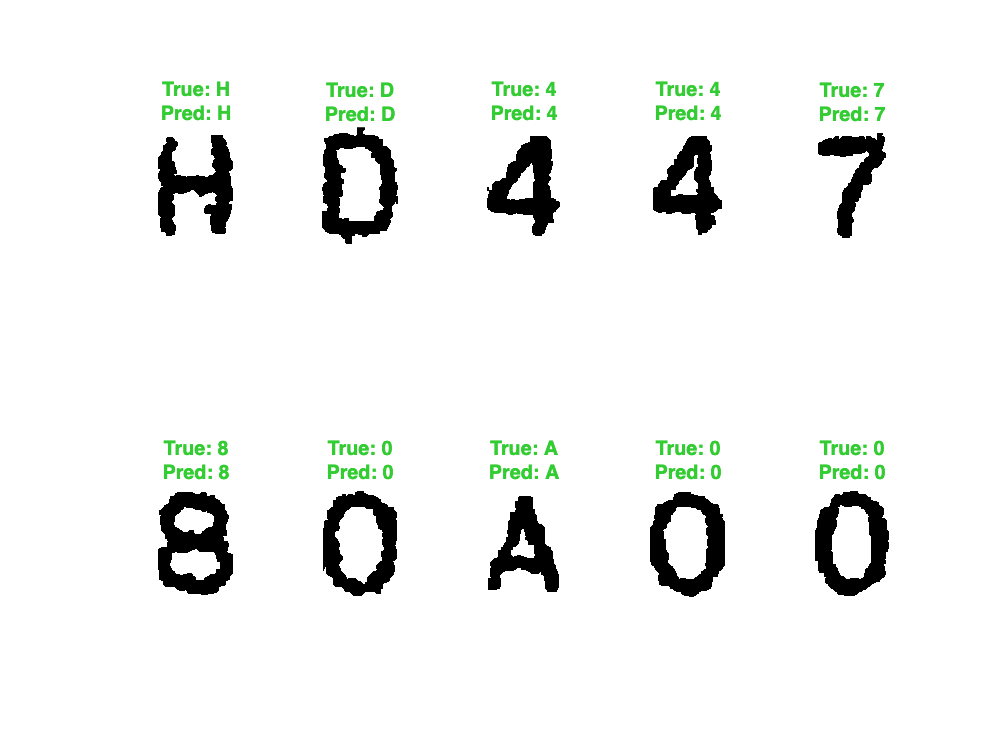

for i = 1:10
    I = readimage(validation, i);
    True_Label = validation_label(i);
    Pred_Label = validation_predicted_label(i);
    subplot(2, 5, i);
    imshow(I);
    if True_Label == Pred_Label
        color = [0.2 0.8 0.2];
    else
        color = [1 0 0];
    end
    title({['True: ' char(True_Label)], ['Pred: ' char(Pred_Label)]},'FontSize', 11,'Color', color);
end